# Laboratorio di Automatica (prova del 31 Gennaio 2020)

Riccardo Antonello ([riccardo.antonello@unipd.it](mail:riccardo.antonello@unipd.it)) and Angelo Cenedese ([angelo.cenedese@unipd.it](mail:angelo.cenedese@unipd.it)) 

January 31, 2020

Dept. of Information Engineering, University of Padova

## Esercizio 2

In Fig. 2 è riportato lo schema di controllo di posizione a tempo discreto di un motore elettrico in corrente continua. Nello schema, $P(z)$ è la funzione di trasferimento dell'impianto, ottenuta considerando la connessione in serie del motore con funzione di trasferimento $P_m(z)$ da ingresso in tensione di armatura $u_a\,[\mathrm{V}]$ ad uscita in posizione $y\,[\mathrm{rad/s}]$, e del driver di tensione con funzione di trasferimento $P_d(z)$ da comando in tensione $u\,[\mathrm{V}]$ a tensione di armatura $u_a\;[\mathrm{V}]$. 

La funzione di trasferimento $P_m(z)$ del motore è ottenuta discretizzando, con il metodo *esatto*, la corrispondente funzione di trasferimento a tempo continuo:


$$P_m(s)\,=\, \frac{Y(s)}{U_a(s)} \,=\, \frac{k_m}{s(T_m s  + 1)}
\qquad\quad\text{con}\qquad\quad
k_m\,=\,5.2\,,\qquad T_m \,=\,0.03$$


mentre per la funzione di trasferimento $P_d(z)$ del driver di tensione si considera un ritardo temporale del tipo:


$$P_d(z) = \frac{U_a(z)}{U(z)} =z^{-N}
\quad\text{con}\quad
N=5$$


Il periodo di campionamento del sistema di controllo si considera pari a $T_s=2\,\mathrm{ms}$.

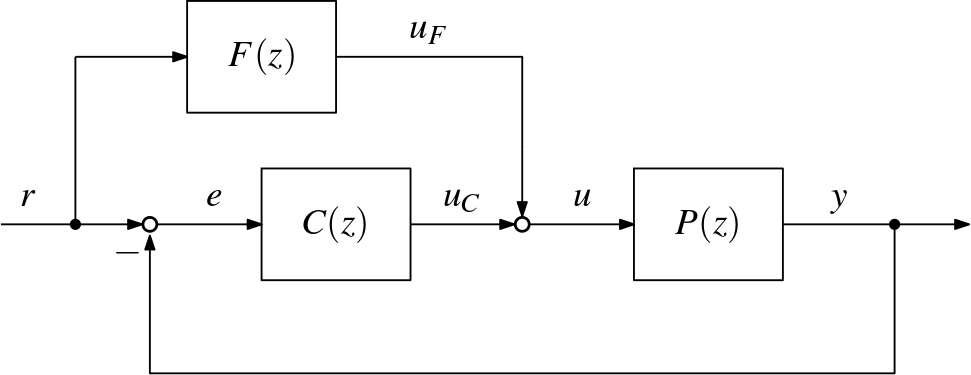

**Figura 2**: Sistema di controllo a tempo discreto.

Utilizzando *soltanto* le routines del Control System Toolbox (CST), si svolgano i seguenti punti:

1) Ricavare le espressioni della funzione di trasferimento $C(z)$ del controllore in retroazione mediante discretizzazione, con i metodi di Eulero in avanti (Forward Euler - FE), Eulero all'indietro (Backward Euler - BE), e Tustin (TU),  della funzione di trasferimento $C(s)$ di un controllore PID ideale a tempo continuo con guadagni:


$$K_P = 15\,,\quad 
K_I = 280\,,\quad
K_D = 0.21$$


Mostrare successivamente, su una stessa figura MATLAB, i diagrammi di Bode del controllore PID a tempo continuo, e delle tre discretizzazioni ottenute con i metodi FE, BE e TU.

*Soluzione*.

%   sampling time
Ts = 2e-3;

%   z-domain var
z = tf('z',Ts);

%   PID controller gains 
kp = 15;
ki = 280;
kd = 0.21;

%   continuous-time controller
sysC = tf([kd, kp, ki], [1,0]);

%   PID controller (FE discretization)
q_FE = (z-1)/Ts;
sysC_FE = kp + ki/q_FE + kd*q_FE;
zpk(sysC_FE)


ans =
 
  105 (z^2 - 1.857z + 0.8625)
  ---------------------------
             (z-1)
 
Sample time: 0.002 seconds
Discrete-time zero/pole/gain model.




%   PID controller (BE discretization)
q_BE = (1-z^-1)/Ts;
sysC_BE = kp + ki/q_BE + kd*q_BE;
zpk(sysC_BE)


ans =
 
  120.56 (z^2 - 1.866z + 0.8709)
  ------------------------------
             z (z-1)
 
Sample time: 0.002 seconds
Discrete-time zero/pole/gain model.




%   PID controller (TU discretization)
q_TU = 2/Ts*(z-1)/(z+1);
sysC_TU = kp + ki/q_TU + kd*q_TU;
zpk(sysC_TU)


ans =
 
  225.28 (z^2 - 1.862z + 0.8668)
  ------------------------------
           (z+1) (z-1)
 
Sample time: 0.002 seconds
Discrete-time zero/pole/gain model.



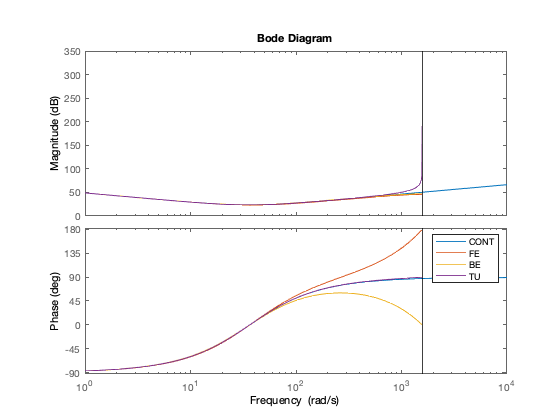


%   Bode plots
figure;
bode(sysC, sysC_FE, sysC_BE, sysC_TU);
legend('CONT', 'FE', 'BE', 'TU');

La versione discretizzata con il metodo di Tustin (TU) è quella il cui diagramma di Bode approssima meglio quello della versione a tempo continuo.

2) Delle tre discretizzazioni ottenute al punto precedente, si consideri quella la cui risposta di fase è approssima meglio quella della corrispondente funzione di trasferimento a tempo continuo. Con l'espressione di $C(z)$ così determinata, e trascurando per il momento il compensatore in feedforward $F(z)$ , si calcoli la funzione di trasferimento del sistema in catena chiusa da riferimento $r$ ad uscita $y$.

Si determini poi la risposta del sistema in catena chiusa ad un riferimento sinusoidale di ampiezza unitaria e frequenza pari a $10\,\mathrm{Hz}$. Mostrare successivamente, in due grafici distinti su una stessa figura MATLAB, l'andamento della risposta sinusoidale e dell'errore di inseguimento $e=r-y$.

Nota: per ricavare la risposta alla sollecitazione sinusoidale, si usi la routine `lsim` del CST.

*Soluzione*.

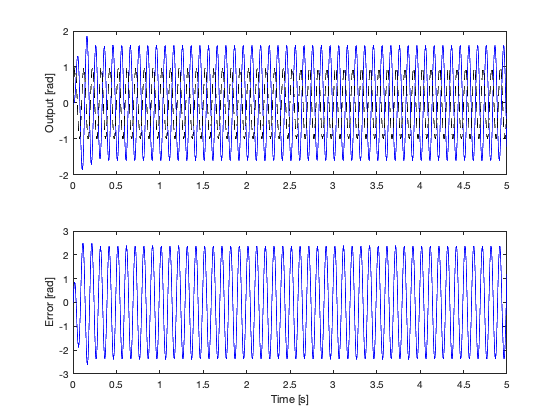

%  continuous-time plant tf
Tm = 0.03;
km = 5.2;
sysP = tf(km, [Tm, 1, 0]);

%   exact discretization of plant model
sysP = c2d(sysP, Ts, 'zoh');

%   add plant delays
N = 5;
sysP = z^-N * sysP;

%   controller tf
sysC = sysC_TU;

%   loop tf
sysL = sysP*sysC;

%   closed-loop tf
sysT = feedback(sysL, 1);

%   sin input
t = 0:Ts:5;
r = sin(2*pi*10*t);

%   sin response
y = lsim(sysT, r, t);
y = y.';

%   tracking error
e = r-y;

%   plot results
figure;
subplot(2,1,1);
plot(t, y, 'b');
hold on
plot(t, r, 'k--');
ylabel('Output [rad]');

subplot(2,1,2);
plot(t, e, 'b');
ylabel('Error [rad]');
xlabel('Time [s]');

3) Si consideri ora un compensatore in feedforward $F(z)$ del tipo:


$$F(z) = \frac{U_F(z)}{R(z)} = z^N\,F\prime(z)$$$


dove $F\prime(z)$ è ottenuto discretizzando, con il metodo di Eulero all'indietro (backward Euler - BE), il compensatore a tempo continuo:


$$F\prime(s)=\frac{T_m}{k_m}s^2 +\frac{1}{k_m}s$$


Determinare la funzione di trasferimento del sistema in catena chiusa, da riferimento $r$ ad uscita $y$.

*Soluzione*.

%   feedforward compensator
sysF = z^N*( (Tm/km)*q_BE^2 + (1/km)*q_BE );

%   closed-loop tf
sysT = minreal( (sysC+sysF)*sysP/(1+sysL), 0.01 );
zpk(sysT)


ans =
 
      0.52168 (z+1.058) (z+0.978) (z-0.5618) (z^2 + 0.4378z + 0.2421)
  -----------------------------------------------------------------------
  (z-0.7267) (z+0.9992) (z^2 + 0.9058z + 0.2955) (z^2 - 0.2381z + 0.3401)
 
Sample time: 0.002 seconds
Discrete-time zero/pole/gain model.



4) Ripetere il punto 2, utilizzando l'espressione del compensatore in feedforward ottenuto al punto 3. Confrontare poi l'ampiezza massima dell'errore di inseguimento $e$ a regime, nel caso di sistema di controllo senza compensazione in feedforwad (punto 2) e con compensazione in feedforward (punto 4).

*Soluzione*.

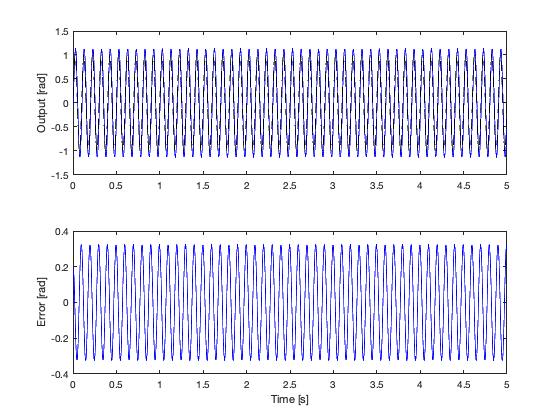

%   sin input
t = 0:Ts:5;
r = sin(2*pi*10*t);

%   sin response
y = lsim(sysT, r, t);
y = y.';

%   tracking error
e = r-y;

%   plot results
figure;
subplot(2,1,1);
plot(t, y, 'b');
hold on
plot(t, r, 'k--');
ylabel('Output [rad]');

subplot(2,1,2);
plot(t, e, 'b');
ylabel('Error [rad]');
xlabel('Time [s]');